## **Q-Learning Background**

Reinforcement learning revolves around the idea of training agents as they interact with their environment through positive feedback.

### **Markov Decision Process**

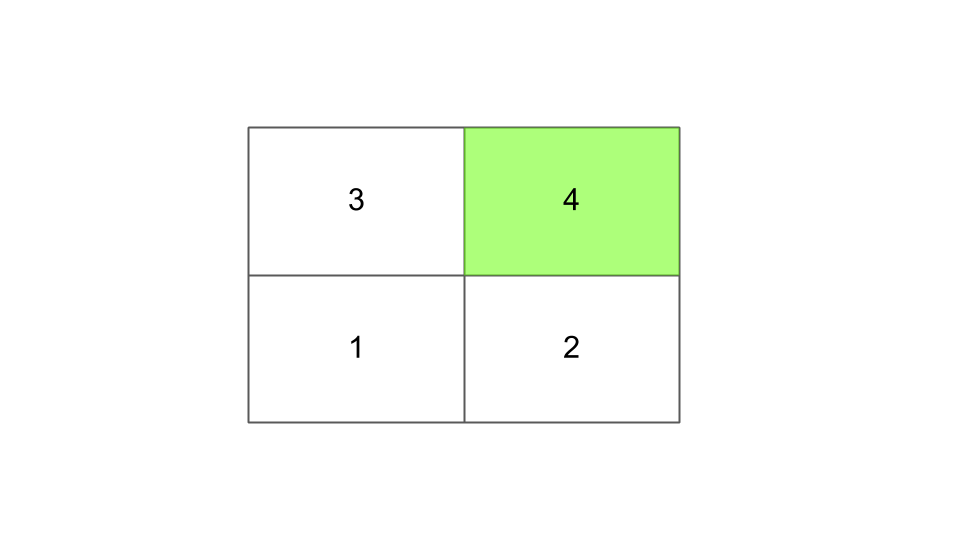

States - S{1, 2, 3 ,4}

Transitions - T1{S1, Up, S3}, T1{S1, Right, S2}

Actions - a{Up, Down, Left, Right}

Rewards

### **Bellman Equation**

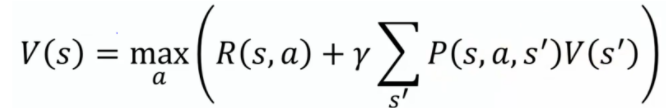

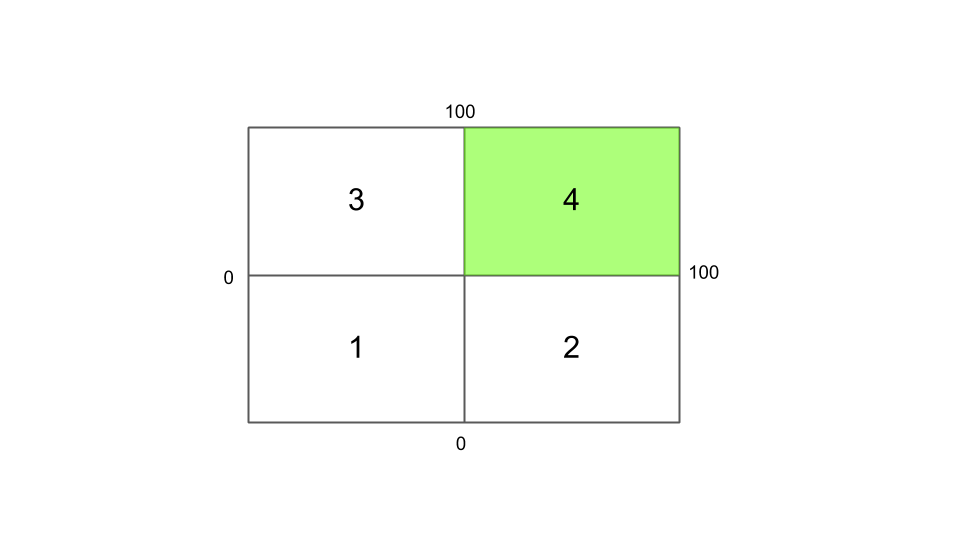

Transitions from 3 or 2 to 4 lead to a reward of 100, while other transitions result in a 0 reward.

#### **Q-learning **


$$Q^{new} (s_t, a_t) = Q^{old} (s_t, a_t) + a*(r_t + \gamma*maxQ(s_{t+1}, a))$$


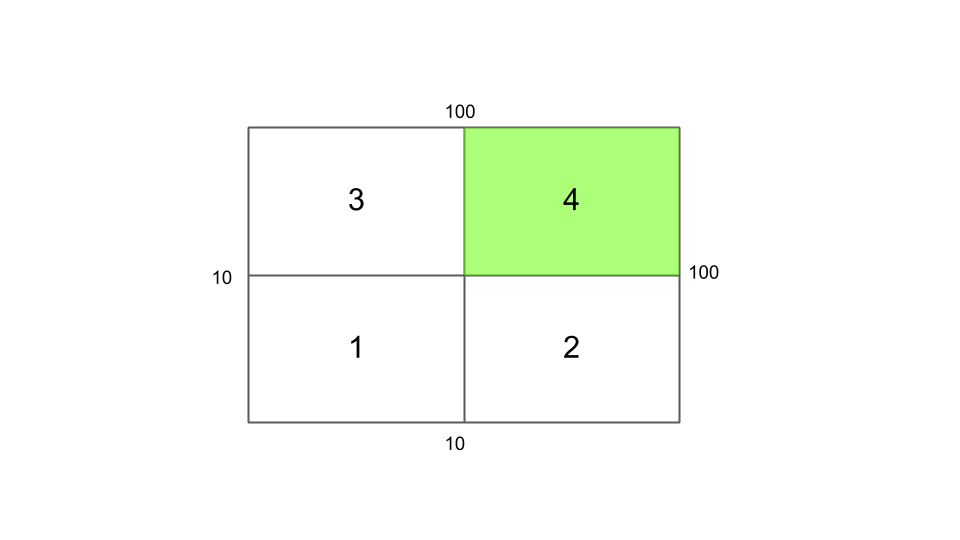

When the discount factor, gamma, is non-zero, future rewards have an effect on the immediately prior transitions.

## Basic Q-Learning Agent Implementation

Q-Learning is implemented with these 5 steps:

- Pick an action based on the highest Q-value.

- Execute action and return: the new agent position, the original position, and the reward for taking that action.

- Determine the maximum potential future reward.

- Update our previous Q-value based on any rewards and the current Q-value dependent on the discount factor.

- Start next episode (iteration) once requirement is met.

First we import our world class which handles the agent's environment.

We will then instantiate a global object from this class so that it can be used by our functions.

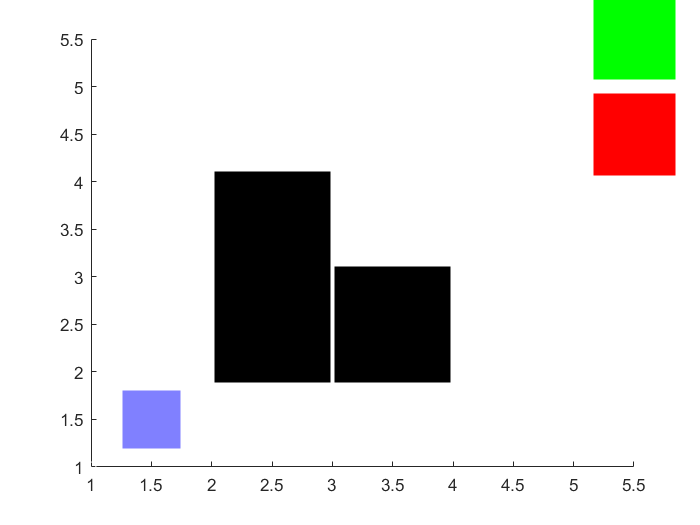

clear
clc
clf

import SmallWorld
global world
world = SmallWorld;
world.render()

We will be training our agent using the "small world" class as it takes only a few iterations.

We will initialize:

Our time at 1,

Our discount value,

The learning_rate,

and the Q table.

We will also declare more global variables.

t = 1;
actions = world.actions;
global Q
global discount
global learning_rate
discount = 0.3;
learning_rate = 1;


% Initialize Q-Table

% For loop adding each state to the Q-table
qkeys = {};
qvalues = {};


for r = 1:world.mapsize
    
    for c = 1:world.mapsize
        % Assign coordinates, action and q to a dictionary
        % Q('ij')('action')||('q')
        index = sub2ind([world.mapsize, world.mapsize], r, c);
        qkeys{r, c} = index;
        temp = ones([1, length(actions)]) * 0.1;
        qvalues{r, c} = containers.Map(actions, temp);    
        
    end
     
end

Q = containers.Map(qkeys, qvalues);

#### Q - States

Our states for the agent are represented by the row and column it is in. Translating these into an index value, we are able to use them as our "key" in a key-value pair. 

disp(Q.keys)

  Columns 1 through 11
    [1]    [2]    [3]    [4]    [5]    [6]    [7]    [8]    [9]    [10]    [11]
  Columns 12 through 20
    [12]    [13]    [14]    [15]    [16]    [17]    [18]    [19]    [20]
  Columns 21 through 25
    [21]    [22]    [23]    [24]    [25]


#### Q - Actions

The actions themselves are another set of key-value pairs with each action being the key, and their Q-value being the value.

disp(Q(1).keys)

    'down'    'left'    'right'    'up'


We setup our Q table using containers to handle key-value pairs to ease our navigation through it.

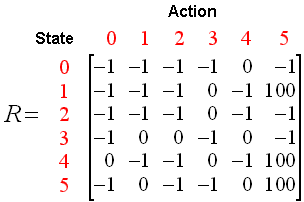

This is not the Q-table but provides an accurate depiction of it.

We would navigate it by calling our state which, as said before, is simply the index of a N-size matrix given a row and column. I.E. Row 1 and Column 2 = State2 or index 2.

This in turn returns a container of key-value pairs of actions and the Q-values associated with them.

Just a recap we in order this is how we navigate the Q-table.

State -> Action -> Value

   1    ->  "Up"   -> 0.1

Following the basic steps from above, we add in a few extra lines to optimize our agent and to constrain how much it runs.

Normally this would be a while loop that we break once our agent met our satisfaction, but for the purpose of this live script, it will be limited with a for loop by the "iterations" variable. Our episodes variable dictates how many times our agent will be allowed to reach an end state of its environment.

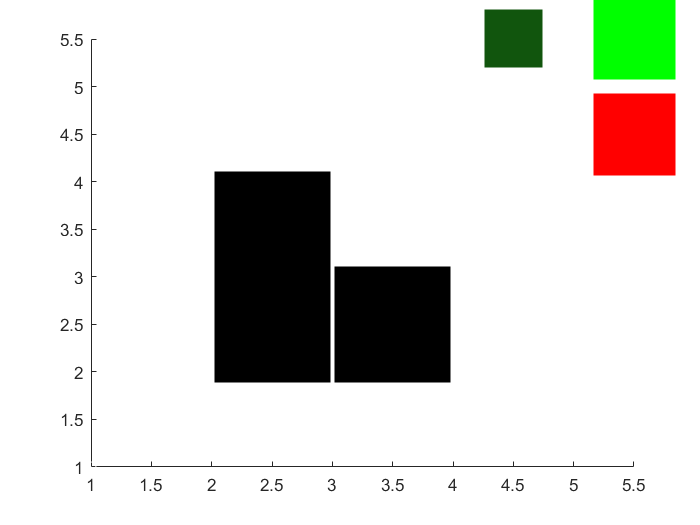

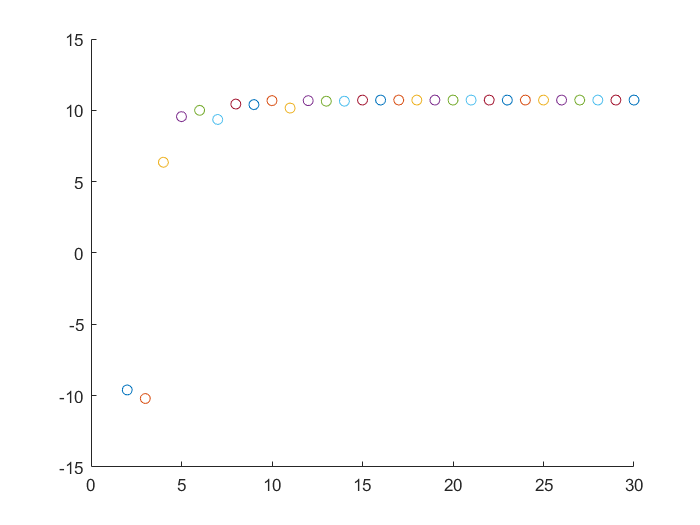

iterations = 1000;
episodes = 1;

% For loop to run the agent
for i = 1 :iterations
    % Pick Action
    [maxq, maxaction] = maxQ(world.player);
    [player, action, reward, newplayer] = take_action(maxaction);

    % Update Q
    [maxq, maxaction] = maxQ(newplayer);
    update_q(player, action, learning_rate, (reward + (discount*maxq)))
    % Check if restart
    t = t + 1;
    if world.restart
        world.restart_program()
        discount = 0.3;
        episodes = episodes + 1;
        if episodes >= 30
            break
        end
    end
    
    % Update learning rate
    learning_rate = power(t,-0.01);
    
    % At the end, render map
    if world.iteration >= 1
        world.render()
    end

    % Pause for readability    
    pause(10^-9)

    if world.iteration >= 750
        break
    end
end

Here we have our function which updates our Q-value. 


$$Q^{new} (s_t, a_t) = Q^{old} (s_t, a_t) + a*(r_t + \gamma*maxQ(s_{t+1}, a))$$


The only difference in our implementation is that we are encouraging "random action". At high learning values, the agent reduces the attention it places on the original award and increases the weight it places on the future reward. As we decrease the learning rate, the agent will increasingly rely on its previous experience;

function update_q(player, action, learning_rate, temporal_dif)
    global Q
    global world
    r = player(1);
    c = player(2);
    index = sub2ind([world.mapsize, world.mapsize], r, c);
    temp_state = Q(index);    
    temp_action = temp_state(action);
    temp_action = temp_action * (1 - learning_rate);
    temp_action = temp_action + (learning_rate * temporal_dif);
    temp_state(action) = temp_action;
    Q(index) = temp_state;
    
    
end





This function navigates our Q-table and dependent on the agent's state, finds the action with the highest Q-value.

function [val, act] = maxQ(player)
    global Q
    global world
    index = sub2ind([world.mapsize, world.mapsize], player(1), player(2));
    val = inf;
    act = "";
    for action = Q(index).keys
        temp = Q(index);
        taction = string(action);
        if val == inf || temp(taction) > val
            val = temp(taction);
            act = string(taction);
        end
    end
    
end


This function updates the agent's state based on an action and returns the updated state and the reward given for taking said action.

function [player, ret_action, reward, newplayer] = take_action(action)
    global world
    actions = world.actions;
    reward = -world.score;
    player = world.player;
    
    if action == string(actions{1})
        world.try_move(1, 0)
        
    elseif action == string(actions{2})
        world.try_move(-1, 0)
        
    elseif action == string(actions{3})
        world.try_move(0, -1)
        
    elseif action == string(actions{4})
        world.try_move(0, 1)
        
    else
        return
    end
    ret_action = action;
    newplayer = world.player;
    reward = reward + world.score;
    
    
end